# Paper3: test multiple things

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3TestingKernelData-RealLGN/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3LGNSpikeData/'];
addpath(DataFolder1)

addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo070724/']; % V1D2
close all

## 2. Set up test parameters

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;

Parameters of:

mono vs. bino

angles

L4 Kernel parameters

AngleList = {'0.0','7.5','15.0','22.5'}; % only vertical for now
MonocuFlagAll = [true];%[true, false];
%ParaIx = 0;   ParaIy = 1;
TestEx = [0,0,0.2, 0.4, 0.6, 1]; 
TestEy = [0,1,1,   1,   1, 0];

% combine the setups
TestExMat = repmat(TestEx,length(MonocuFlagAll),1); 
TestEyMat = repmat(TestEy,length(MonocuFlagAll),1);
TestExSeq = TestExMat(:); TestEySeq = TestEyMat(:); 

MonocuFlagMat = repmat(MonocuFlagAll',1,length(TestEx));
MonocuFlagSeq = MonocuFlagMat(:);

TestNum = length(MonocuFlagSeq);
% can be only 0 or 45 for now
AngleTestAll = 0*ones(size(MonocuFlagSeq)); 

## E/I depression & L4E->L6 conversion

first get basic function information

Too time comsuming. --->> using HPC

close all
lgnSF = 2.5; lgnTF = 10;

ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
L6pars{3} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
L6pars{1} = {2.5,3,62.5,86,86};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118}; % 142.2; 166.7

figure(101)
xx = 0:0.1:100;
hold on
for L6Id = 1:3
    yy = L6Convert(xx,L6pars{L6Id});
    plot(xx,yy,'DisplayName',sprintf('L6Convert-%d',L6Id))
end
grid on
xlim([0 90])
ylim([0 120])
xlabel('L4E')
ylabel('frL6')
legend('Location','SouthEast')

IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKpUse = IKp3;

figure(102)
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'};
% we are using the L4eL6 conversion curve formula for L4E depression
xx = 0:0.1:220;
hold on
yy = L6Convert(xx,EKpUse);
plot(xx,yy,'DisplayName',sprintf('L4E-depression'))
xlabel('L4E')
ylabel('L4E-dep')
grid on

close all

Load CG and LIF data

LGNsmear = n_S_HC*0.2;
TruncLGN = 1;
Conn_Reduc_Test = 5;
if MonocuFlagAll
    LoadStr = 'Mono'
else
    LoadStr = 'Bino'
end

LoadStr = 'Mono'


SaveStr = [LoadStr 'L6RealCtrlL4'];
SaveStrUse = sprintf('%s_Ag%d_RealLGNSF%.1fTF%d_Ereduc%d',...
    SaveStr,AngleTestAll(1),lgnSF,lgnTF,Conn_Reduc_Test);

load([SaveToFolder sprintf('SameEIKer-EIDep_%s.mat',SaveStrUse)],...
    'LDEOutAll')

%% Load LGN spiking data!
LGN1Data = load(sprintf('LGN_Cell1_Row0.12_Col0.15_deg0.0_SF%.1f_TF%d_TSimu25.mat',...
                        lgnSF, lgnTF),'SpTimeMix'); % 1-cell config doesn't care about orientation
LGN2Data = load(sprintf('LGN_Cell2_Row0.12_Col0.15_deg90.0_SF%.1f_TF%d_TSimu25.mat',...
                        lgnSF, lgnTF),'SpTimeMix'); % 2-cell for C only; ortho
LGN4DataAll = cell(13,1); LGN6DataAll = cell(13,1);
AngAll = 0:7.5:90; % all simulated LGN angles
for AngId = 1:length(AngAll)
    LGN4DataAll{AngId} = load(sprintf('LGN_Cell4_Row0.14_Col0.15_deg%.1f_SF%.1f_TF%d_TSimu25.mat',...
                                       AngAll(AngId),lgnSF, lgnTF),'SpTimeMix');
    % For 4-cell, rowdist is 0.14
    LGN6DataAll{AngId} = load(sprintf('LGN_Cell6_Row0.12_Col0.15_deg%.1f_SF%.1f_TF%d_TSimu25.mat',...
                                       AngAll(AngId),lgnSF, lgnTF),'SpTimeMix');  
    % For 6-cell, rowdist is 0.12
end

**5. Reexamination: Current decomposition!**

first get relevant pixel list

XXs = 1:NPixX; YYs = 1:2*NPixY;
PixNum4Curr = length(XXs)*length(YYs);
[Xall, Yall] = meshgrid(XXs,YYs);
PixList4Curr = ...
    (Xall(:)-1) * N_HCOutY *NPixY + Yall(:);
PixInfoAll = cell(size(AngleTestAll));
TestIdAll = [1, 6, 12, 18, 31];
BGflag = false(size(TestIdAll));

For each test; for each pixel considered

for TestId = 5%1:TestNum
    PixInfoAll{TestId}.Frs = zeros(3,length(PixList4Curr));
    PixInfoAll{TestId}.L4Ec = zeros(3,length(PixList4Curr));
    PixInfoAll{TestId}.L4Ic = zeros(3,length(PixList4Curr));
    PixInfoAll{TestId}.LGNc = zeros(3,length(PixList4Curr));
    PixInfoAll{TestId}.L6c  = zeros(3,length(PixList4Curr));
    PixInfoAll{TestId}.ambc = zeros(3,length(PixList4Curr));
    AngleInpt = AngleTestAll(TestId)
    
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

Prepare LGN and L6 firing rates

    Angles_4Input = Angle + [0 45 90 135];
    lgn_SOnOff = [45+abs(mod(Angles_4Input,180)-90)/2;
        45-abs(mod(Angles_4Input,180)-90)/2]/1e3;
    % redefine low-up bounds for L6: [10 54]
    NL6S = NS_L6; NL6C = NC_L6; NL6I = NI_L6;

    lgn_SOnOff = [45+(cosd(abs(mod(Angles_4Input,180))*2)+1)/2*45;
        45-(cosd(abs(mod(Angles_4Input,180))*2)+1)/2*45]/1e3;


    %% NOTE: Now we are computing for binocular, and has to mix BG and drive
    lgn_SOnOff = [lgn_SOnOff, [0.02;0.02]];
    lgn_COnOff = [0.045*ones(2,4),[0.02;0.02]];
    lgn_IOnOff = [0.045*ones(1,4),0.02];

Copied from part 3 above

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 5; L6list = 5;
    OD_SMapModi = OD_SMap;
    %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
    MonocuFlag = MonocuFlagSeq(TestId)
    if MonocuFlag
        OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;  
        SaveStr = 'Monocu';
    else
        SaveStr = 'Binocu';
    end

L6 kernel

    L6ConvSig = 0.75;
    L6ConvTruc = 1.5/(L6ConvSig);
    Kersize = floor(2*L6ConvSig*L6ConvTruc);
    if Kersize<=0
        Kersize= 2; % at least 1
    end
    [x,y] = meshgrid(1:Kersize,1:Kersize);
    c = Kersize/2;
    exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
    L6Kernel = exp(-exponent);
    L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
    L6Kernel = L6Kernel + ...
        L6Kernel(end:-1:1,:) + ...
        L6Kernel(:,end:-1:1) + ...
        L6Kernel(end:-1:1,end:-1:1);%symmetrize
    L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
    L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
    L6Kernel(2,2) = 0.3;

LGN and L6 are blurred 

    N_HCold = 3; % shrink to 2*2
    FigOn = false;
    LGNsmear = n_S_HC*0.2;
    TruncLGN = 1;
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
        N_HCold,n_S_HC,LGNsmear,TruncLGN,FigOn);

    if ~MonocuFlag
        LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
    end

    PixLGNCtgr = LGNIndSpat_Rec(...
        LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

    % symmetrize !! This is actually trick, so I do it ad hoc
    PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

    MirInd = logical(MirInd);
    CtgrOrder = [2,1;3,4]; % for lower left HC
    CtgrOrderUse = rot90(CtgrOrder,RotInd);
    if MirInd
        %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
        CtgrOrderUse = flip(CtgrOrderUse,1);
    end
    CtgrOrderReadout = ...
        [CtgrOrderUse(1,2);
        CtgrOrderUse(1,1);
        CtgrOrderUse(2,1);
        CtgrOrderUse(2,2)];
    %    for Ctgr = 1:4
    %         PixL6Ctgr(:,Ctgr) = ...
    %             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
    %         PixLGNCtgr(:,Ctgr) = ...
    %             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
    %    end

    % let's implement something cheap now for 45 deg
    PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);
    if BGflag(TestId)
        PixLGNCtgr(:,1:4) = 0;
        PixLGNCtgr(:,5) = 1;
    end
    
    % finally compute the corresponding L6 and LGN firing rates
    %L6RateMap = %PixL6Ctgr * FL6_Angle1';
    lgn_SOnOffMap = PixLGNCtgr * lgn_SOnOff';
    lgn_COnOffMap = PixLGNCtgr * lgn_COnOff';
    lgn_IOnOffMap = PixLGNCtgr * lgn_IOnOff';


Now compute L4E and I frs

    ParaEx = TestExSeq(TestId) 
    ParaEy = TestEySeq(TestId)
    ParaIx = ParaEx; ParaIy = ParaEy;

    C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

    Conn_Reduc_Test = 5;
    Reduc_S = Conn_Reduc_Test*(1-CplxR); Reduc_C = Conn_Reduc_Test*CplxR;
    P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
    P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
    P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
    P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Confirming L4E/I input after depression

    Test = TestIdAll(TestId);
    LDEEquv = LDEOutAll{Test}{end}; 
    LDEEquv.E = LDEEquv.S * (1-0.3077) + LDEEquv.C * 0.3077;
    LDEUse = LDEEquv;
    LDEUseEAdj = L6Convert(LDEUse.E,EKpUse)./LDEUse.E;
    LDEUse.S = LDEUse.S .* LDEUseEAdj;
    LDEUse.C = LDEUse.C .* LDEUseEAdj;
    LDEUse.I   = InhMulp(LDEEquv.I, IKpUse);
    LDEUse.E = LDEUse.S * (1-0.3077) + LDEUse.C * 0.3077;

    L4EUse_S = (C_SS_meanU*LDEUse.S + C_SC_meanU*LDEUse.C);
    L4EUse_C = (C_CS_meanU*LDEUse.S + C_CC_meanU*LDEUse.C);
    L4EUse_I = (C_IS_mean*LDEUse.S + C_IC_mean*LDEUse.C);

    L4IUse_S = (C_SI_mean*LDEUse.I);
    L4IUse_C = (C_CI_mean*LDEUse.I);
    L4IUse_I = (C_II_mean*LDEUse.I);

    % Obtain the L6 input
    FieldRow = N_HCOutY * NPixY;
    FieldCol = floor(length(LDEUse.E)/FieldRow);
    L4Efield = reshape(LDEUse.E,FieldRow,FieldCol);
    L4Efield_padded = padarray(L4Efield, [1, 1], 'circular'); % Pad B for periodic boundary conditions
    C = conv2(L4Efield_padded, L6Kernel, 'same'); % Perform convolution with periodic boundary conditions
    %% The slope of L6 is adjustable
    L6EUse = L6Convert(C(2:end-1, 2:end-1),L6pars{2});% Extract the part of L6 that corresponds to the original dimensions of B

    %L61*(C(2:end-1, 2:end-1)-L62);
    L6EUse(L6EUse>120) = 120; L6EUse(L6EUse<3) = 3; % for now, I can't handel fL6>120 Hz since I didn't precompute that
    % compute the L6 plane that I should refer to. 3 = layer 1; 120 = layer
    % 40, and interpolate the rest.
    L6RateMap = L6EUse(:); % should be 1-33

    HyperPara = {20*1e3};
    tic
    for PixCurrTest = 1:PixNum4Curr
        PixId = PixList4Curr(PixCurrTest);
        L4SEU = L4EUse_S(PixId); L4SIU = L4IUse_S(PixId);
        L4CEU = L4EUse_C(PixId); L4CIU = L4IUse_C(PixId);
        L4IEU = L4EUse_I(PixId); L4IIU = L4IUse_I(PixId);
        rL6SU = NS_L6 * L6RateMap(PixId) * 1e-3;
        rL6CU = NC_L6 * L6RateMap(PixId) * 1e-3;
        rL6IU = NI_L6 * L6RateMap(PixId) * 1e-3;
        lgn_SU = lgn_SOnOffMap(PixId,:)';
        lgn_CU = lgn_COnOffMap(PixId,:)';
        lgn_I = lgn_IOnOffMap(PixId,:);
        
        [f_EnIOut,...
            L4ERcdMat,L4IRcdMat, ...
            LGNRcdMat,L6RcdMat,ambRcdMat]...
            = LIFo_SinglePixel_CurrDecomp(...
            ...% MF Parameters
            LGNFreq, L4SEU,L4SIU, L4CEU,L4CIU, L4IEU,L4IIU,... %3
            S_EE,S_EI,S_IE,S_II,p_EEFail,... %5
            S_EL6,S_IL6,rL6SU,rL6CU,rL6IU,S_amb,rS_amb,rC_amb,rI_amb,...%7 L6 Amb
            lgn_SU, lgn_CU,lgn_I,N_Slgn,N_Clgn,N_Ilgn, S_Elgn,S_Ilgn,... %7
            ...% A big problem:  lgn_COnOff,lgn_I was unquoted - so using 45 Hz by defalut
            gL_E,gL_I,Ve,Vi, tau_ref,... %5
            ...% Below are LIF details
            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,... %7
            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,... %4
            HyperPara);% if varagin non empty, we only export the last state
        
        PixInfoAll{TestId}.Frs(:,PixCurrTest) = mean(f_EnIOut(:,floor(end/2):end),2);
        PixInfoAll{TestId}.L4Ec(:,PixCurrTest) = mean(L4ERcdMat(:,floor(end/2):end),2);
        PixInfoAll{TestId}.L4Ic(:,PixCurrTest) = mean(L4IRcdMat(:,floor(end/2):end),2);
        PixInfoAll{TestId}.LGNc(:,PixCurrTest) = mean(LGNRcdMat(:,floor(end/2):end),2);
        PixInfoAll{TestId}.L6c(:,PixCurrTest) = mean(L6RcdMat(:,floor(end/2):end),2);
        PixInfoAll{TestId}.ambc(:,PixCurrTest) = mean(ambRcdMat(:,floor(end/2):end),2);
    end
    toc

    save figs, finally data

    CurrDecompStr = sprintf('x%.2fy%.2f_%s_%s',ParaEx,ParaEy,SaveStr,SaveStrUse)
    Fig4 = figure("Name",sprintf('CurrDecomp_%s',CurrDecompStr),...
    'units','normalized','outerposition',[0,0,0.5,1]);
    subplot(2,2,1)
    ShowField_Rec(...
        (PixInfoAll{TestId}.Frs(1,:)*(1-CplxR) +...
        PixInfoAll{TestId}.Frs(2,:)*CplxR)', ...
        1:PixNum4Curr,1*NPixX,2*NPixY)
    title('frE');
    subplot(2,2,2)
    ShowField_Rec(...
        (PixInfoAll{TestId}.L4Ec(1,:)*(1-CplxR) +...
         PixInfoAll{TestId}.L4Ec(2,:)*CplxR)', ...
        1:PixNum4Curr,1*NPixX,2*NPixY)
    title('L4E Curr');
    subplot(2,2,3)
    ShowField_Rec(...
        abs((PixInfoAll{TestId}.L4Ic(1,:)*(1-CplxR) +...
             PixInfoAll{TestId}.L4Ic(2,:)*CplxR)'), ...
        1:PixNum4Curr,1*NPixX,2*NPixY)
    title('L4I Curr');
    subplot(2,2,4)
    TheRestCurr = PixInfoAll{TestId}.LGNc + PixInfoAll{TestId}.L6c ...
        + PixInfoAll{TestId}.ambc;
    ShowField_Rec(...
        (TheRestCurr(1,:)*(1-CplxR) +...
         TheRestCurr(2,:)*CplxR)', ...
         1:PixNum4Curr,1*NPixX,2*NPixY)
    title('Other Curr');

    FigName4 = sprintf('CurrDecomp_%s',CurrDecompStr);
    savefig(Fig4,[FigurePaperPath FigName4 '.fig']);

    Fig4.PaperUnits = 'centimeters';
    Fig4.PaperSize = [36,28];
    Fig4.PaperOrientation = "landscape";
    exportgraphics(Fig4,[FigurePaperPath FigName4 '.pdf'],'Resolution',150)
    close all
end

AngleInpt = 0

MonocuFlag = logical
   1


ParaEx = 0.6000

ParaEy = 1

Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LGN input
Drive regime. Use Phase variant LG

Elapsed time is 219.245320 seconds.


CurrDecompStr = 'x0.60y1.00_Monocu_MonoL6RealCtrlL4_Ag0_RealLGNSF2.5TF10_Ereduc5'


DataCurrFileName = ...
    [SaveToFolder sprintf('TestKernel_MultiPars_Curr_%s.mat',SaveStrUse)];

save(DataCurrFileName,...
   'PixInfoAll',...
   'AngleList','MonocuFlagSeq','TestExSeq','TestEySeq')


**Compare two cases**

TestIdReff = 3;

ParaEx = TestExSeq(TestIdReff);
ParaEy = TestEySeq(TestIdReff);
ParaIx = ParaEx; ParaIy = ParaEy;
Conn_Reduc_Test = 5;

[C_SS_meanU,C_CS_meanU,C_IS_mean,...
 C_SC_meanU,C_CC_meanU,C_IC_mean,...
 C_SI_mean, C_CI_mean, C_II_mean] = ...
    GetCGConnMats(...
    C_SS_Pixel_Us,C_CS_Pixel_Us,C_IS_Pixel_Us,...
    C_SC_Pixel_Us,C_CC_Pixel_Us,C_IC_Pixel_Us,...
    C_SI_Pixel_Us,C_CI_Pixel_Us,C_II_Pixel_Us,...
    N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,...
    ParaEx,ParaEy,ParaIx,ParaIy,...
    Conn_Reduc_Test,CplxR,N_SS,N_SC,N_CS,N_CC);

MonocuFlag = MonocuFlagSeq(TestIdReff)

MonocuFlag = logical
   1


if MonocuFlag
    SaveStr = 'Monocu';
else
    SaveStr = 'Binocu';
end

TestIdComp = 4;
ParaExComp = TestExSeq(TestIdComp);
ParaEyComp = TestEySeq(TestIdComp);
ParaIxComp = ParaExComp; ParaIyComp = ParaEyComp;

[C_SS_meanUComp,C_CS_meanUComp,C_IS_meanComp,...
 C_SC_meanUComp,C_CC_meanUComp,C_IC_meanComp,...
 C_SI_meanComp, C_CI_meanComp, C_II_meanComp] = ...
    GetCGConnMats(...
    C_SS_Pixel_Us,C_CS_Pixel_Us,C_IS_Pixel_Us,...
    C_SC_Pixel_Us,C_CC_Pixel_Us,C_IC_Pixel_Us,...
    C_SI_Pixel_Us,C_CI_Pixel_Us,C_II_Pixel_Us,...
    N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,...
    ParaExComp,ParaEyComp,ParaIxComp,ParaIyComp,...
    Conn_Reduc_Test,CplxR,N_SS,N_SC,N_CS,N_CC);

MonocuFlagComp = MonocuFlagSeq(TestIdComp)

MonocuFlagComp = logical
   0


if MonocuFlagComp
    SaveStrComp = 'Monocu';
else
    SaveStrComp = 'Binocu';
end

### CG comparison

FrEBG = 4.6; FrIBG = 17.1;

if MonocuFlag || MonocuFlagComp % if either is monocu
    CtgrPix = ...
        [10,5
         6, 10
         1, 6
         5, 1
         10,15
         6, 20
         1, 16
         5, 11]; % compair the center of all 8 ODs in both bands
else % both are binocu
    CtgrPix = ...
        [10,5
         6, 10
         1, 6
         5, 1]; % only one band, since the other would be identical
end
PixTxt = 'a':char('a'+length(CtgrPix)-1);
% Quantities we concern
FrEPixs = zeros(length(CtgrPix),2); FrIPixs = zeros(length(CtgrPix),2); 
FrEBand = zeros(2,2); FrIBand = zeros(2,2);

Figure dispiay

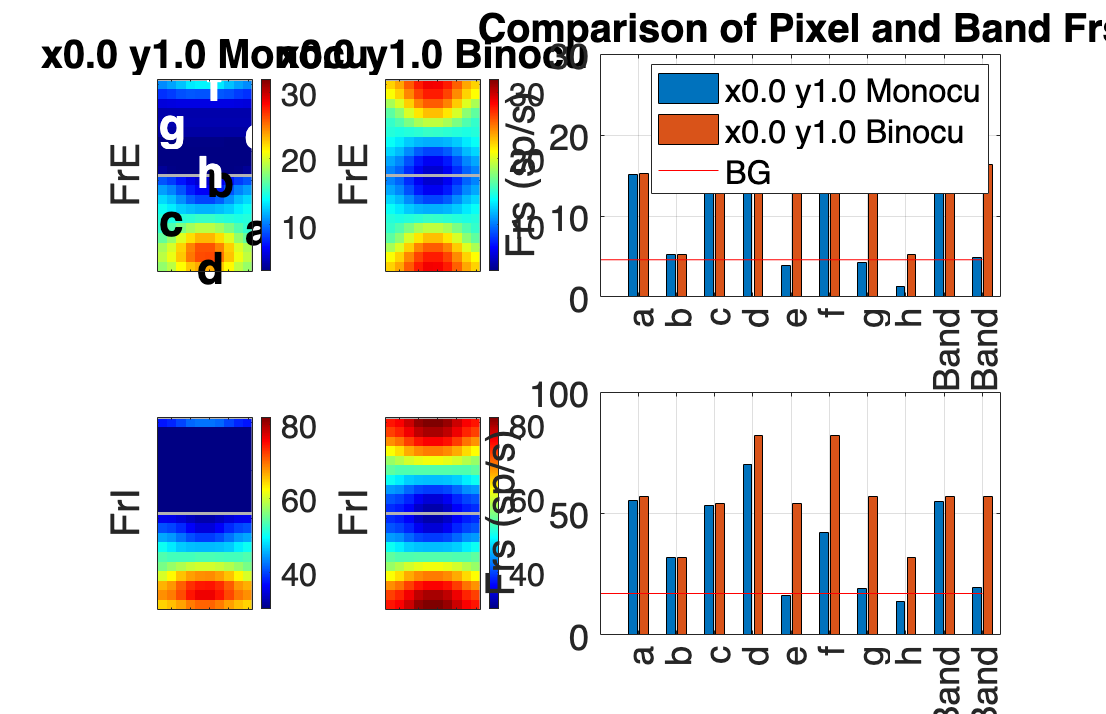

FigCGComp = figure("Name",'CGComp',...
    'units','normalized','outerposition',[0,0,1,1]);
TestIDAll = [TestIdReff,TestIdComp]; TestXAll = [ParaEx,ParaExComp]; 
TestYAll = [ParaEy,ParaEyComp]; MonoStrAll = {SaveStr,SaveStrComp};
TitleDisp = cell(3,1); TitleDisp{3} = 'BG';
for PlotId = 1:length(TestIDAll)
    % E
    subplot(2,length(TestIDAll)+2,PlotId)
    TestId = TestIDAll(PlotId);
    TitleDisp{PlotId} = sprintf('x%.1f y%.1f %s',TestXAll(PlotId),TestYAll(PlotId),MonoStrAll{PlotId});
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY,TitleDisp{PlotId},[3 32])
    axis([0.5 10.5 0.5 20.5])
    ylabel('FrE')
    set(gca,'FontSize',18)
        % Pixel Frs
    PattS = LDEOutAll{TestId}{end}.S;
    PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
    PattC = LDEOutAll{TestId}{end}.C;
    PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
    PattE = PattS * (1-CplxR) + PattC * CplxR;

    if PlotId == 1 % label the pixels
        for PixInd = 1:length(CtgrPix)
            clear text
            PixX = CtgrPix(PixInd,1); PixY = CtgrPix(PixInd,2);
            txt = text(PixX-0.3, PixY+0.1, PixTxt(PixInd),...
                'FontSize',22,'FontWeight','bold');
            if PixInd >4
                txt.Color = [1,1,1];
            end
        end                    
    end
    for PixInd = 1:length(CtgrPix)
        PixX = CtgrPix(PixInd,1); PixY = CtgrPix(PixInd,2);
        FrEPixs(PixInd,PlotId) = PattE(PixY,PixX);
    end
    FrEBand(1,PlotId) = sum(PattE(1:NPixY,1:NPixX),'all')/(NPixY*NPixX); % driven band
    FrEBand(2,PlotId) = sum(PattE(NPixY+1:2*NPixY,1:NPixX),'all')/(NPixY*NPixX); % undriven band
   
    % I
    subplot(2,length(TestIDAll)+2,PlotId+length(TestIDAll)+2)
    TestId = TestIDAll(PlotId);
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY,'',[30 82])
    axis([0.5 10.5 0.5 20.5])
    ylabel('FrI')
    set(gca,'FontSize',18)
        % Pixel Frs
    PattI = LDEOutAll{TestId}{end}.I;
    PattI = reshape(PattI,NPixY*N_HCOutY,NPixX*N_HCOutX);
    for PixInd = 1:length(CtgrPix)
        PixX = CtgrPix(PixInd,1); PixY = CtgrPix(PixInd,2);
        FrIPixs(PixInd,PlotId) = PattI(PixY,PixX);
    end
    FrIBand(1,PlotId) = sum(PattI(1:NPixY,1:NPixX),'all')/(NPixY*NPixX); % driven band
    FrIBand(2,PlotId) = sum(PattI(NPixY+1:2*NPixY,1:NPixX),'all')/(NPixY*NPixX); % undriven band
end
% clustered bar graphs
subplot(2,length(TestIDAll)+2,length(TestIDAll)+1:length(TestIDAll)+2)
bar([FrEPixs;FrEBand], 'grouped');
title('Comparison of Pixel and Band Frs')
ylabel('Frs (sp/s)')
xticklabels([num2cell(PixTxt),'Driven Band','Undriven Band'])
set(gca,'FontSize',18)
grid on
hold on
plot(0:length([FrEPixs;FrEBand]),FrEBG*ones(size(0:length([FrEPixs;FrEBand]))),'r')
legend(TitleDisp)

subplot(2,length(TestIDAll)+2,2*length(TestIDAll)+3:2*length(TestIDAll)+4)
bar([FrIPixs;FrIBand], 'grouped');
ylabel('Frs (sp/s)')
xticklabels([num2cell(PixTxt),'Driven Band','Undriven Band'])
set(gca,'FontSize',18)
hold on
plot(0:length([FrIPixs;FrIBand]),FrIBG*ones(size(0:length([FrIPixs;FrIBand]))),'r')
grid on


CurrDecompStr = sprintf('x%dy%d%s-x%dy%d%s-%s',...
    ParaEx,ParaEy,SaveStr,ParaExComp,ParaEyComp,SaveStrComp,SaveStrUse)

CurrDecompStr = 'x0y1Monocu-x0y1Binocu-Ag45_L60.25_1.32_Ereduc5'

FigName5 = sprintf('CGComp_%s',CurrDecompStr);
savefig(FigCGComp,[FigurePaperPath FigName5 '.fig']);

FigCGComp.PaperUnits = 'centimeters';
FigCGComp.PaperSize = [42,23];
FigCGComp.PaperOrientation = "landscape";
exportgraphics(FigCGComp,[FigurePaperPath FigName5 '.pdf'],'Resolution',150)
close all

### Current decomposition (LIF) of corresponding trails

XXs = 1:NPixX; YYs = 1:2*NPixY;
PixNum4Curr = length(XXs)*length(YYs);

Use Reff as standard, then do first order approximation of currents for the Comp case

CurrDecompStr = sprintf('x%dy%d_x%dy%d_%s_%s',...
    ParaEx,ParaEy,ParaExComp,ParaEyComp,SaveStr,SaveStrUse)

CurrDecompStr = 'x0y1_x0y1_Monocu_Ag45_L60.25_1.32_Ereduc5'

Fig5 = figure("Name",sprintf('CurrInvest_%s',CurrDecompStr),...
    'units','normalized','outerposition',[0,0.3,1,1]);
Panel1 = 2; Panel2 = 6;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.05 .05],[.05 .05],[.10 .10]);

First Give all color scales:

FrE, EL4E, EL4I, FrI, IL4E, IL4I

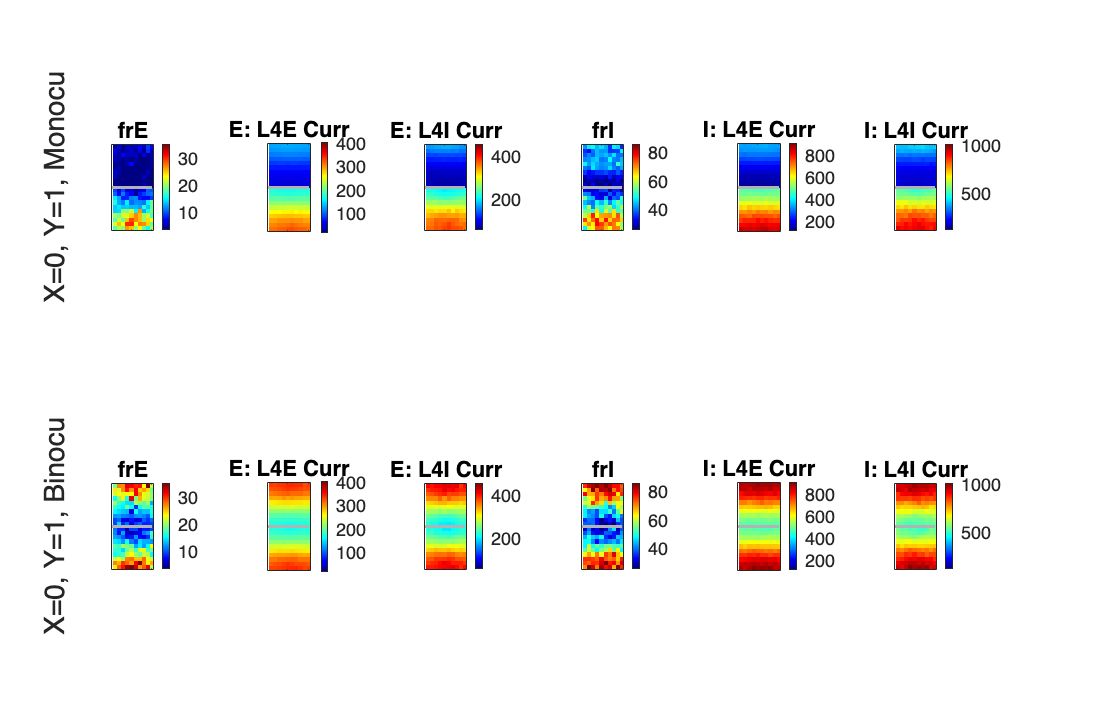

CAxesAll = [3 35; 10 400; 50 450; 25 85; 100 900; 100 1000];
axes(ha(1));
FrEReff = (PixInfoAll{TestIdReff}.Frs(1,:)*(1-CplxR) +...
           PixInfoAll{TestIdReff}.Frs(2,:)*CplxR)';
ShowField_Rec(FrEReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'frE',CAxesAll(1,:))
ylabel(sprintf('X=%d, Y=%d, %s\n',ParaEx,ParaEy,SaveStr),...
    'Interpreter','tex','FontSize',14);

axes(ha(2));
EL4EcReff = (PixInfoAll{TestIdReff}.L4Ec(1,:)*(1-CplxR) +...
             PixInfoAll{TestIdReff}.L4Ec(2,:)*CplxR)';
ShowField_Rec(EL4EcReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'E: L4E Curr',CAxesAll(2,:))

axes(ha(3));
EL4IcReff = (PixInfoAll{TestIdReff}.L4Ic(1,:)*(1-CplxR) +...
             PixInfoAll{TestIdReff}.L4Ic(2,:)*CplxR)';
ShowField_Rec(abs(EL4IcReff), ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'E: L4I Curr',CAxesAll(3,:))

axes(ha(4));
FrIReff = (PixInfoAll{TestIdReff}.Frs(3,:))';
ShowField_Rec(FrIReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'frI',CAxesAll(4,:))

axes(ha(5));
IL4EcReff = (PixInfoAll{TestIdReff}.L4Ec(3,:))';
ShowField_Rec(IL4EcReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'I: L4E Curr',CAxesAll(5,:))

axes(ha(6));
IL4IcReff = (PixInfoAll{TestIdReff}.L4Ic(3,:))';
ShowField_Rec(abs(IL4IcReff), ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'I: L4I Curr',CAxesAll(6,:))
% subplot(2,2,4)
% TheRestCurr = PixInfoAll{TestId}.LGNc + PixInfoAll{TestId}.L6c ...
%     + PixInfoAll{TestId}.ambc;
% ShowField_Rec(...
%     (TheRestCurr(1,:)*(1-CplxR) +...
%     TheRestCurr(2,:)*CplxR)', ...
%     1:PixNum4Curr,1*NPixX,2*NPixY)
% title('Other Curr');
axes(ha(6+1));
FrEReff = (PixInfoAll{TestIdComp}.Frs(1,:)*(1-CplxR) +PixInfoAll{TestIdComp}.Frs(2,:)*CplxR)';
ShowField_Rec(FrEReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'frE',CAxesAll(1,:))
title('frE');
ylabel(sprintf('X=%d, Y=%d, %s\n',ParaExComp,ParaEyComp,SaveStrComp),...
    'Interpreter','tex','FontSize',14);

axes(ha(6+2));
EL4EcReff = (PixInfoAll{TestIdComp}.L4Ec(1,:)*(1-CplxR) +PixInfoAll{TestIdComp}.L4Ec(2,:)*CplxR)';
ShowField_Rec(EL4EcReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'E: L4E Curr',CAxesAll(2,:))

axes(ha(6+3));
EL4IcReff = (PixInfoAll{TestIdComp}.L4Ic(1,:)*(1-CplxR) +PixInfoAll{TestIdComp}.L4Ic(2,:)*CplxR)';
ShowField_Rec(abs(EL4IcReff), ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'E: L4I Curr',CAxesAll(3,:))

axes(ha(6+4));
FrIReff = (PixInfoAll{TestIdComp}.Frs(3,:))';
ShowField_Rec(FrIReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'frI',CAxesAll(4,:))

axes(ha(6+5));
IL4EcReff = (PixInfoAll{TestIdComp}.L4Ec(3,:))';
ShowField_Rec(IL4EcReff, ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'I: L4E Curr',CAxesAll(5,:))

axes(ha(6+6));
IL4IcReff = (PixInfoAll{TestIdComp}.L4Ic(3,:))';
ShowField_Rec(abs(IL4IcReff), ...
    1:PixNum4Curr,1*NPixX,2*NPixY,'I: L4I Curr',CAxesAll(6,:))


FigName5 = sprintf('CurrInvest_%s',CurrDecompStr);
savefig(Fig5,[FigurePaperPath FigName5 '.fig']);

Fig5.PaperUnits = 'centimeters';
Fig5.PaperSize = [42,23];
Fig5.PaperOrientation = "landscape";
exportgraphics(Fig5,[FigurePaperPath FigName5 '.pdf'],'Resolution',150)
close all

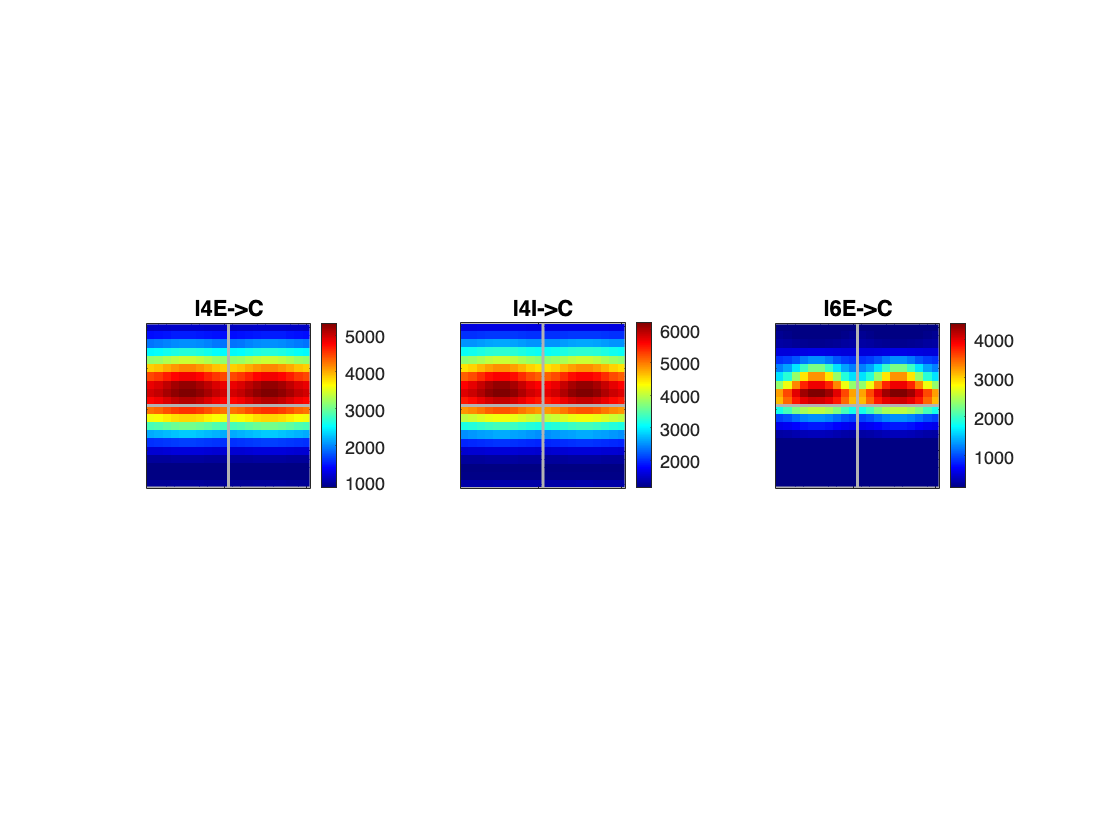

close all
figure
subplot 131
ShowField_Rec(L4EUse_C, 1:3200,40,80)
title('l4E->C')
subplot 132
ShowField_Rec(L4IUse_C, 1:3200,40,80)
title('l4I->C')
subplot 133
ShowField_Rec(NC_L6 * L6RateMap(:), 1:3200,40,80)
title('l6E->C')

subplot 131
axis([0.5 20.5 10.5 30.5])
subplot 132
axis([0.5 20.5 10.5 30.5])
subplot 133
axis([0.5 20.5 10.5 30.5])
subplot 131
axis square
subplot 132
axis square
subplot 133
axis square